x = xdata;
y = ydata;
ft = fittype('a + b*x - c*(x).*(x>0.2) + d')

ft =      General model:
     ft(a,b,c,d,x) = a + b*x - c*(x).*(x>0.2) + d

f = fit(x,y,ft,'start',[0 0 0 0])

f =      General model:
     f(x) = a + b*x - c*(x).*(x>0.2) + d
     Coefficients (with 95% confidence bounds):
       a =      0.2546  (-5.776e+13, 5.776e+13)
       b =     -0.5097  (-0.5639, -0.4555)
       c =     -0.1247  (-0.1732, -0.07609)
       d =      0.2546  (-5.776e+13, 5.776e+13)

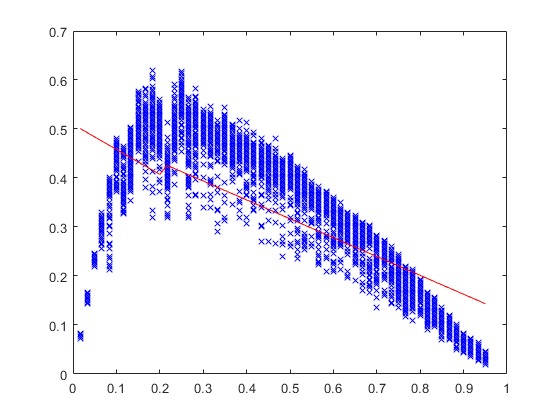

plot(x,y,'bx',x,f(x),'r-')